NG'ETHE BERNICE WANJIKU 

ENM221-0085/2017

B. Sc. MECHATRONIC ENGINEERING

YEAR: 4               SEMESTER: I

VIBRATIONS        EMT 2436

LAB WORK

L = 1                   %length of string

L = 1

n = [1 2 3 4 5 10 20 ]  %limits for summation

n =      1     2     3     4     5    10    20


lngd = string(n)        %create sting from the values of n

lngd = 1×7 string array
    "1"    "2"    "3"    "4"    "5"    "10"    "20"


x = 0:0.01:1            %Divide the wave into 100 portions

x =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


% Get values of y = f(x) 
% the triangular wave is divided into four eaqual parts: U!, U2, U3, U4
% each part extends 1/4 of the whole length
U1 = 0:(1/25):1

U1 =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000


U2 = flip(U1)

U2 =     1.0000    0.9600    0.9200    0.8800    0.8400    0.8000    0.7600    0.7200    0.6800    0.6400    0.6000    0.5600    0.5200    0.4800    0.4400    0.4000    0.3600    0.3200    0.2800    0.2400    0.2000    0.1600    0.1200    0.0800    0.0400         0


U3 = U1*-1

U3 =          0   -0.0400   -0.0800   -0.1200   -0.1600   -0.2000   -0.2400   -0.2800   -0.3200   -0.3600   -0.4000   -0.4400   -0.4800   -0.5200   -0.5600   -0.6000   -0.6400   -0.6800   -0.7200   -0.7600   -0.8000   -0.8400   -0.8800   -0.9200   -0.9600   -1.0000


U4 = U2*-1

U4 =    -1.0000   -0.9600   -0.9200   -0.8800   -0.8400   -0.8000   -0.7600   -0.7200   -0.6800   -0.6400   -0.6000   -0.5600   -0.5200   -0.4800   -0.4400   -0.4000   -0.3600   -0.3200   -0.2800   -0.2400   -0.2000   -0.1600   -0.1200   -0.0800   -0.0400         0


%drop the first element of each subsequent part 
% as it repeated in the last elemnt of the preceeding part
U = [U1 U2(2:end) U3(2:end) U4(2:end)] 

U =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400    0.8000    0.7600    0.7200    0.6800    0.6400    0.6000    0.5600    0.5200    0.4800    0.4400    0.4000    0.3600    0.3200    0.2800    0.2400    0.2000    0.1600    0.1200    0.0800    0.0400


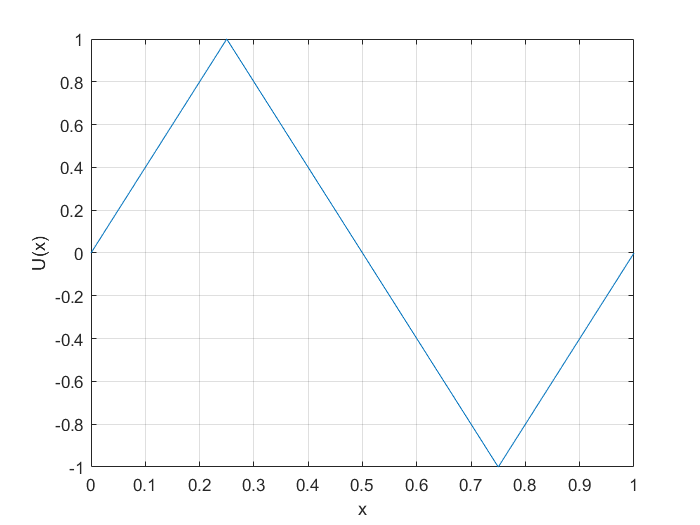


%plot the graph of U vs x
plot(x,U)
xlabel('x')
xlabel('x')
ylabel('U(x)')
grid on

syms k
f_FS = zeros(1, length(x)) %initiate the fourier half series eqn

f_FS =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fx = U

fx =          0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400    0.8000    0.7600    0.7200    0.6800    0.6400    0.6000    0.5600    0.5200    0.4800    0.4400    0.4000    0.3600    0.3200    0.2800    0.2400    0.2000    0.1600    0.1200    0.0800    0.0400


A0 = 2/L * integral(@(x) fx, 0, L,'ArrayValued',true )

A0 =          0    0.0800    0.1600    0.2400    0.3200    0.4000    0.4800    0.5600    0.6400    0.7200    0.8000    0.8800    0.9600    1.0400    1.1200    1.2000    1.2800    1.3600    1.4400    1.5200    1.6000    1.6800    1.7600    1.8400    1.9200    2.0000    1.9200    1.8400    1.7600    1.6800    1.6000    1.5200    1.4400    1.3600    1.2800    1.2000    1.1200    1.0400    0.9600    0.8800    0.8000    0.7200    0.6400    0.5600    0.4800    0.4000    0.3200    0.2400    0.1600    0.0800


for j=1:length(n)
    for i=1:length(x)
        fun1 = @(m) fx(i) * cos((pi*n(j)*m)/L)
        fun2 = @(m) fx(i) * sin((pi*n(j)*m)/L)
        An = (2/L) * integral(fun1, 0, L,'ArrayValued',true)   
        Bn = (2/L) * integral(fun2, 0, L,'ArrayValued',true)
        f= (An* cos((pi*n(j)*x(i))/L)) + (Bn * sin((pi*n(j)*x(i))/L))
        
        % Fourier half series
        f_FS(i) = (A0(i)/2) + symsum(f, k, 1, n(j))      
        
    end
   
    plot(x,f_FS, 'LineWidth',2.0)
    hold on 
end 

fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.0358e-18

Bn = 0.0509

f = 0.0016

f_FS =          0    0.0416         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.0715e-18

Bn = 0.1019

f = 0.0064

f_FS =          0    0.0416    0.0864         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.0715e-18

Bn = 0.1528

f = 0.0144

f_FS =          0    0.0416    0.0864    0.1344         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.2143e-17

Bn = 0.2037

f = 0.0255

f_FS =          0    0.0416    0.0864    0.1344    0.1855         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 0.2546

f = 0.0398

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.2143e-17

Bn = 0.3056

f = 0.0573

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = 0.3565

f = 0.0778

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 0.4074

f = 0.1013

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.0817e-17

Bn = 0.4584

f = 0.1279

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 0.5093

f = 0.1574

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 0.5602

f = 0.1898

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 0.6112

f = 0.2250

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.5919e-17

Bn = 0.6621

f = 0.2629

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 0.7130

f = 0.3036

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.3267e-17

Bn = 0.7639

f = 0.3468

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 0.8149

f = 0.3926

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.6328e-17

Bn = 0.8658

f = 0.4407

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.1633e-17

Bn = 0.9167

f = 0.4912

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 0.9677

f = 0.5439

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.0186

f = 0.5987

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-17

Bn = 1.0695

f = 0.6555

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 5.5511e-17

Bn = 1.1205

f = 0.7142

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 9.7145e-17

Bn = 1.1714

f = 0.7746

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 1.2223

f = 0.8367

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 1.2732

f = 0.9003

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 1.2223

f = 0.8910

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 9.7145e-17

Bn = 1.1714

f = 0.8787

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 5.5511e-17

Bn = 1.1205

f = 0.8633

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-17

Bn = 1.0695

f = 0.8451

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.0186

f = 0.8241

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 0.9677

f = 0.8003

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.1633e-17

Bn = 0.9167

f = 0.7740

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.6328e-17

Bn = 0.8658

f = 0.7452

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 0.8149

f = 0.7141

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252    1.3541         0         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.3267e-17

Bn = 0.7639

f = 0.6807

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252    1.3541    1.2807         0         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 0.7130

f = 0.6452

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252    1.3541    1.2807    1.2052         0         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.5919e-17

Bn = 0.6621

f = 0.6076

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252    1.3541    1.2807    1.2052    1.1276         0         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 0.6112

f = 0.5682

f_FS =          0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851    1.6241    1.5603    1.4940    1.4252    1.3541    1.2807    1.2052    1.1276    1.0482         0         0         0         0         0         0         0         0         0         0         0


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 0.5602

f = 0.5271

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 0.5093

f = 0.4844

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.0817e-17

Bn = 0.4584

f = 0.4402

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 0.4074

f = 0.3946

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = 0.3565

f = 0.3479

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.2143e-17

Bn = 0.3056

f = 0.3002

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 0.2546

f = 0.2515

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.2143e-17

Bn = 0.2037

f = 0.2021

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.0715e-18

Bn = 0.1528

f = 0.1521

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.0715e-18

Bn = 0.1019

f = 0.1017

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.0358e-18

Bn = 0.0509

f = 0.0509

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.0358e-18

Bn = -0.0509

f = -0.0509

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.0715e-18

Bn = -0.1019

f = -0.1017

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.0715e-18

Bn = -0.1528

f = -0.1521

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.2143e-17

Bn = -0.2037

f = -0.2021

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -0.2546

f = -0.2515

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.2143e-17

Bn = -0.3056

f = -0.3002

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = -0.3565

f = -0.3479

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -0.4074

f = -0.3946

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0817e-17

Bn = -0.4584

f = -0.4402

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -0.5093

f = -0.4844

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -0.5602

f = -0.5271

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -0.6112

f = -0.5682

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.5919e-17

Bn = -0.6621

f = -0.6076

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -0.7130

f = -0.6452

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.3267e-17

Bn = -0.7639

f = -0.6807

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -0.8149

f = -0.7141

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.6328e-17

Bn = -0.8658

f = -0.7452

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.1633e-17

Bn = -0.9167

f = -0.7740

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -0.9677

f = -0.8003

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.0186

f = -0.8241

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-17

Bn = -1.0695

f = -0.8451

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.5511e-17

Bn = -1.1205

f = -0.8633

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -9.7145e-17

Bn = -1.1714

f = -0.8787

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -1.2223

f = -0.8910

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = -1.2732

f = -0.9003

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -1.2223

f = -0.8367

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -9.7145e-17

Bn = -1.1714

f = -0.7746

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.5511e-17

Bn = -1.1205

f = -0.7142

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-17

Bn = -1.0695

f = -0.6555

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.0186

f = -0.5987

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -0.9677

f = -0.5439

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.1633e-17

Bn = -0.9167

f = -0.4912

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.6328e-17

Bn = -0.8658

f = -0.4407

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -0.8149

f = -0.3926

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.3267e-17

Bn = -0.7639

f = -0.3468

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -0.7130

f = -0.3036

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.5919e-17

Bn = -0.6621

f = -0.2629

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -0.6112

f = -0.2250

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -0.5602

f = -0.1898

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -0.5093

f = -0.1574

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0817e-17

Bn = -0.4584

f = -0.1279

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -0.4074

f = -0.1013

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = -0.3565

f = -0.0778

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.2143e-17

Bn = -0.3056

f = -0.0573

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -0.2546

f = -0.0398

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.2143e-17

Bn = -0.2037

f = -0.0255

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.0715e-18

Bn = -0.1528

f = -0.0144

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.0715e-18

Bn = -0.1019

f = -0.0064

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.0358e-18

Bn = -0.0509

f = -0.0016

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0416    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-19

Bn = -7.6436e-18

f = -1.3456e-18

f_FS = 1×101
         0    0.0400    0.0864    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-18

Bn = -1.5287e-17

f = -3.6370e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1344    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -1.3010e-17

f = -5.8459e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1855    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -3.0575e-17

f = -1.0964e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2398    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-18

Bn = 2.9273e-17

f = 1.0696e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2973    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -2.6021e-17

f = -1.6031e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.3578    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -6.0715e-18

f = -1.5142e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.4213    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -6.1149e-17

f = -3.5539e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.4879    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-17

Bn = -3.2309e-17

f = -2.6100e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.5574    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 5.8547e-17

f = 3.7220e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.6298    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 1.4311e-17

f = 2.7835e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.7050    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -5.2042e-17

f = -4.5741e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.7829    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -1.9516e-17

f = -3.0851e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.8636    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.2143e-17

f = -2.7048e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.9468    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -8.0231e-17

f = -8.1223e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    1.0326    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -1.2230e-16

f = -1.1070e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    1.1207    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = -9.5410e-18

f = -8.3608e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    1.2112    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0817e-17

Bn = -6.4618e-17

f = -6.7332e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    1.3039    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 1.3444e-17

f = 9.9456e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    1.3987    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 1.1709e-16

f = 1.1351e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    1.4955    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -4.2501e-17

f = -3.9440e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    1.5942    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 2.8623e-17

f = 3.7217e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    1.6946    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = -6.9389e-18

f = -5.1448e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    1.7967    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.0408e-16

f = -1.0562e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.9003    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 1.0408e-17

f = 1.0408e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    1.8510    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.0408e-16

f = -1.0214e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    1.7987    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = -6.9389e-18

f = -8.6235e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    1.7433    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.8572e-17

Bn = 2.8623e-17

f = 1.9014e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    1.6851


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -4.2501e-17

f = -4.2891e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 1.1709e-16

f = 1.0922e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 1.3444e-17

f = 1.5054e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0817e-17

Bn = -6.4618e-17

f = -4.9605e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = -9.5410e-18

f = -8.3608e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -1.2230e-16

f = -9.5824e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -8.0231e-17

f = -4.8594e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.7756e-17

Bn = -1.2143e-17

f = 8.3357e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -1.9516e-17

f = 2.3987e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -5.2042e-17

f = -2.5509e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 1.4311e-17

f = -9.5903e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 5.8547e-17

f = 3.1606e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-17

Bn = -3.2309e-17

f = -8.5241e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -6.1149e-17

f = -2.3378e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = -6.0715e-18

f = 9.9719e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -2.6021e-17

f = -3.1273e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-18

Bn = 2.9273e-17

f = 7.3962e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -3.0575e-17

f = -4.2431e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -1.3010e-17

f = 9.7008e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-18

Bn = -1.5287e-17

f = -1.9496e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-19

Bn = -7.6436e-18

f = 3.8570e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-19

Bn = 7.6436e-18

f = -1.3456e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-18

Bn = 1.5287e-17

f = -3.6370e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 1.3010e-17

f = -5.8459e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 3.0575e-17

f = -1.0964e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-18

Bn = -2.9273e-17

f = 1.0696e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 2.6021e-17

f = -1.6031e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 6.0715e-18

f = -1.5142e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 6.1149e-17

f = -3.5539e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-17

Bn = 3.2309e-17

f = -2.6100e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -5.8547e-17

f = 3.7220e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -1.4311e-17

f = 2.7835e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 5.2042e-17

f = -4.5741e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 1.9516e-17

f = -3.0851e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.2143e-17

f = -2.7048e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 8.0231e-17

f = -8.1223e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 1.2230e-16

f = -1.1070e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 9.5410e-18

f = -8.3608e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.0817e-17

Bn = 6.4618e-17

f = -6.7332e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -1.3444e-17

f = 9.9456e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -1.1709e-16

f = 1.1351e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 4.2501e-17

f = -3.9440e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -2.8623e-17

f = 3.7217e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = 6.9389e-18

f = -5.1448e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.0408e-16

f = -1.0562e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = -1.0408e-17

f = 1.0408e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.0408e-16

f = -1.0214e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3878e-17

Bn = 6.9389e-18

f = -8.6235e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.8572e-17

Bn = -2.8623e-17

f = 1.9014e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = 4.2501e-17

f = -4.2891e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -6.9389e-18

Bn = -1.1709e-16

f = 1.0922e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = -1.3444e-17

f = 1.5054e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.0817e-17

Bn = 6.4618e-17

f = -4.9605e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 9.5410e-18

f = -8.3608e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 1.2230e-16

f = -9.5824e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 8.0231e-17

f = -4.8594e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.7756e-17

Bn = 1.2143e-17

f = 8.3357e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4286e-17

Bn = 1.9516e-17

f = 2.3987e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 5.2042e-17

f = -2.5509e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4286e-17

Bn = -1.4311e-17

f = -9.5903e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-18

Bn = -5.8547e-17

f = 3.1606e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-17

Bn = 3.2309e-17

f = -8.5241e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 6.1149e-17

f = -2.3378e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3878e-17

Bn = 6.0715e-18

f = 9.9719e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 6.9389e-18

Bn = 2.6021e-17

f = -3.1273e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-18

Bn = -2.9273e-17

f = 7.3962e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 3.0575e-17

f = -4.2431e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-18

Bn = 1.3010e-17

f = 9.7008e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-18

Bn = 1.5287e-17

f = -1.9496e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-19

Bn = 7.6436e-18

f = 3.8570e-19

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.1684e-18

Bn = 0.0170

f = 0.0016

f_FS = 1×101
         0    0.0448    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-18

Bn = 0.0340

f = 0.0064

f_FS = 1×101
         0    0.0448    0.0991    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-18

Bn = 0.0509

f = 0.0142

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-18

Bn = 0.0679

f = 0.0250

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-17

Bn = 0.0849

f = 0.0385

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-18

Bn = 0.1019

f = 0.0546

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.6429e-17

Bn = 0.1188

f = 0.0728

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.1358

f = 0.0930

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 5.2042e-17

Bn = 0.1528

f = 0.1146

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-17

Bn = 0.1698

f = 0.1373

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.5103e-17

Bn = 0.1867

f = 0.1607

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.2037

f = 0.1843

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.2207

f = 0.2076

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.2858e-17

Bn = 0.2377

f = 0.2302

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-16

Bn = 0.2546

f = 0.2515

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-17

Bn = 0.2716

f = 0.2711

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.3267e-17

Bn = 0.2886

f = 0.2885

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-16

Bn = 0.3056

f = 0.3032

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.6328e-17

Bn = 0.3226

f = 0.3148

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-16

Bn = 0.3395

f = 0.3229

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3184e-16

Bn = 0.3565

f = 0.3272

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 9.0206e-17

Bn = 0.3735

f = 0.3273

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    0.9200    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.1102e-16

Bn = 0.3905

f = 0.3229

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    0.9600    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-17

Bn = 0.4074

f = 0.3139

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.0000    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.4980e-16

Bn = 0.4244

f = 0.3001

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    0.9600    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-17

Bn = 0.4074

f = 0.2597

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    0.9200    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.1102e-16

Bn = 0.3905

f = 0.2195

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    0.8800    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 9.0206e-17

Bn = 0.3735

f = 0.1799

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    0.8400


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.3184e-16

Bn = 0.3565

f = 0.1416

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-16

Bn = 0.3395

f = 0.1049

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.6328e-17

Bn = 0.3226

f = 0.0704

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-16

Bn = 0.3056

f = 0.0383

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.3267e-17

Bn = 0.2886

f = 0.0091

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.4694e-17

Bn = 0.2716

f = -0.0171

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.0408e-16

Bn = 0.2546

f = -0.0398

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 7.2858e-17

Bn = 0.2377

f = -0.0591

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.2207

f = -0.0748

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.2037

f = -0.0867

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.5103e-17

Bn = 0.1867

f = -0.0951

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-17

Bn = 0.1698

f = -0.0998

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 5.2042e-17

Bn = 0.1528

f = -0.1010

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 1.7347e-17

Bn = 0.1358

f = -0.0990

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 3.6429e-17

Bn = 0.1188

f = -0.0939

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-18

Bn = 0.1019

f = -0.0860

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-17

Bn = 0.0849

f = -0.0756

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 8.6736e-18

Bn = 0.0679

f = -0.0631

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-18

Bn = 0.0509

f = -0.0489

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 4.3368e-18

Bn = 0.0340

f = -0.0334

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 2.1684e-18

Bn = 0.0170

f = -0.0169

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.1684e-18

Bn = -0.0170

f = 0.0169

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-18

Bn = -0.0340

f = 0.0334

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-18

Bn = -0.0509

f = 0.0489

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-18

Bn = -0.0679

f = 0.0631

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-17

Bn = -0.0849

f = 0.0756

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-18

Bn = -0.1019

f = 0.0860

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.6429e-17

Bn = -0.1188

f = 0.0939

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.1358

f = 0.0990

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.2042e-17

Bn = -0.1528

f = 0.1010

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-17

Bn = -0.1698

f = 0.0998

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.5103e-17

Bn = -0.1867

f = 0.0951

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.2037

f = 0.0867

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.2207

f = 0.0748

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.2858e-17

Bn = -0.2377

f = 0.0591

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-16

Bn = -0.2546

f = 0.0398

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-17

Bn = -0.2716

f = 0.0171

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.3267e-17

Bn = -0.2886

f = -0.0091

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-16

Bn = -0.3056

f = -0.0383

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.6328e-17

Bn = -0.3226

f = -0.0704

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-16

Bn = -0.3395

f = -0.1049

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3184e-16

Bn = -0.3565

f = -0.1416

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -9.0206e-17

Bn = -0.3735

f = -0.1799

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.1102e-16

Bn = -0.3905

f = -0.2195

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-17

Bn = -0.4074

f = -0.2597

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.4980e-16

Bn = -0.4244

f = -0.3001

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-17

Bn = -0.4074

f = -0.3139

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.1102e-16

Bn = -0.3905

f = -0.3229

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -9.0206e-17

Bn = -0.3735

f = -0.3273

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.3184e-16

Bn = -0.3565

f = -0.3272

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-16

Bn = -0.3395

f = -0.3229

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.6328e-17

Bn = -0.3226

f = -0.3148

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-16

Bn = -0.3056

f = -0.3032

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.3267e-17

Bn = -0.2886

f = -0.2885

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.4694e-17

Bn = -0.2716

f = -0.2711

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0408e-16

Bn = -0.2546

f = -0.2515

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.2858e-17

Bn = -0.2377

f = -0.2302

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.2207

f = -0.2076

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.2037

f = -0.1843

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.5103e-17

Bn = -0.1867

f = -0.1607

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-17

Bn = -0.1698

f = -0.1373

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.2042e-17

Bn = -0.1528

f = -0.1146

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.7347e-17

Bn = -0.1358

f = -0.0930

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -3.6429e-17

Bn = -0.1188

f = -0.0728

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-18

Bn = -0.1019

f = -0.0546

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-17

Bn = -0.0849

f = -0.0385

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.6736e-18

Bn = -0.0679

f = -0.0250

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-18

Bn = -0.0509

f = -0.0142

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -4.3368e-18

Bn = -0.0340

f = -0.0064

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.1684e-18

Bn = -0.0170

f = -0.0016

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = 0

Bn = 0

f = 0

f_FS = 1×101
         0    0.0448    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.4745e-17

Bn = -3.5779e-18

f = -1.5077e-17

f_FS = 1×101
         0    0.0400    0.0991    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.9490e-17

Bn = -7.1557e-18

f = -3.0343e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1626    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.9490e-17

Bn = -1.2577e-17

f = -3.2049e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.2350    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.8981e-17

Bn = -1.4311e-17

f = -5.8580e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.3156    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.1124e-17

Bn = -5.8547e-18

f = -6.0982e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.4037    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -5.8981e-17

Bn = -2.5153e-17

f = -6.0214e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.4985    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -7.8063e-17

Bn = -1.6914e-17

f = -6.2791e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.5989    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.1796e-16

Bn = -2.8623e-17

f = -8.7374e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.7038    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -8.3267e-17

Bn = -3.7297e-17

f = -6.9200e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.8120    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.4225e-16

Bn = -1.1709e-17

f = -5.5093e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.9222    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.0061e-16

Bn = -8.6736e-19

f = -1.9705e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    1.0330    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.1796e-16

Bn = -5.0307e-17

f = -5.7615e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    1.1429    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.5959e-16

Bn = -5.8981e-17

f = -4.8843e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    1.2506    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.5613e-16

Bn = -3.3827e-17

f = -3.9730e-18

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    1.3545    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0123e-16

Bn = 5.5511e-17

f = 1.1498e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    1.4533    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = -5.7246e-17

f = 4.8653e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    1.5454    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.9143e-16

Bn = -2.6021e-18

f = 1.5396e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    1.6295    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.6653e-16

Bn = -7.4593e-17

f = 4.8677e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    1.7044    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -1.8041e-16

Bn = -1.0408e-16

f = 6.0264e-17

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    1.7687    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.8449e-16

Bn = -2.3419e-17

f = 2.1640e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    1.8216    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = 4.5103e-17

f = 2.2847e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    1.8619    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.0123e-16

Bn = -1.7347e-18

f = 1.8646e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    1.8888    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = 4.1633e-17

f = 2.3886e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    1.9018    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = -1.0061e-16

f = 2.2145e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.9003    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.9837e-16

Bn = -4.6838e-17

f = 2.9837e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    1.7391    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = -1.0061e-16

f = 2.4667e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    1.5784    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


fun2 = function_handle with value:
    @(m)fx(i)*sin((pi*n(j)*m)/L)


An = -2.3592e-16

Bn = 4.1633e-17

f = 2.1816e-16

f_FS = 1×101
         0    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6400    0.6800    0.7200    0.7600    0.8000    0.8400    0.8800    0.9200    0.9600    1.0000    0.9600    0.9200    1.4198    1.2648


fun1 = function_handle with value:
    @(m)fx(i)*cos((pi*n(j)*m)/L)


legend(lngd)
xlabel('x')
ylabel('f(x)')
hold off
